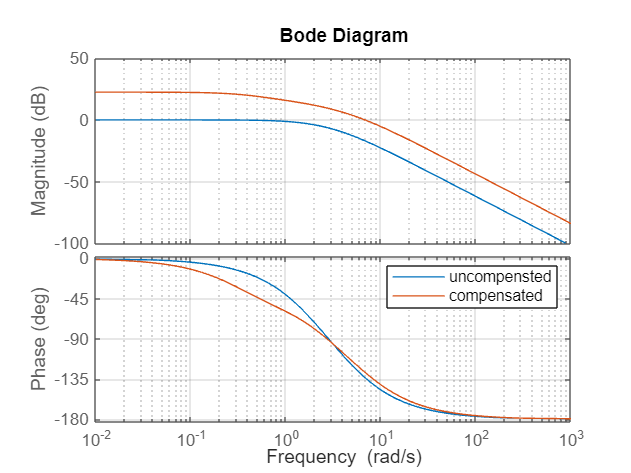

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G = 8/(s^2 + 6*s+8);%%open loopTf for uncompensated sytem

% Proposed compensators
G_lead = 8*(s+1)/(s+6);%%lead comaparator
G_lag  = (s+4)/(s+0.4);
G_T= G_lead * G_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T = feedback(G_T * G, 1);

% bode plot for uncompenated system and compensated system
figure;
bode(G, G_T*G); 
legend('uncompensted','compensated');
grid on;

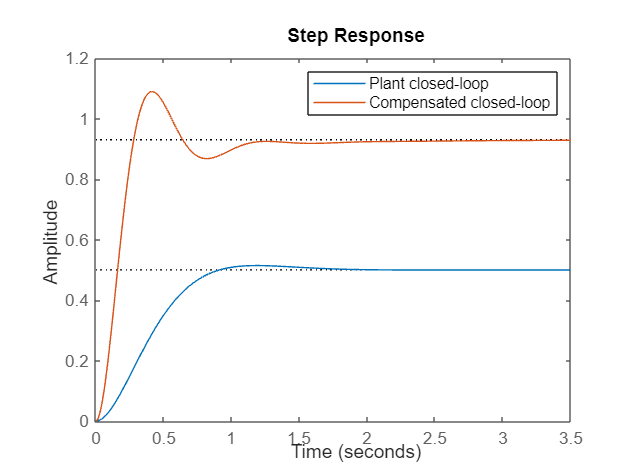

Step info for compensated case 1:


         RiseTime: 0.1890
    TransientTime: 1.0753
     SettlingTime: 1.0753
      SettlingMin: 0.8380
      SettlingMax: 1.0895
        Overshoot: 17.1222
       Undershoot: 0
             Peak: 1.0895
         PeakTime: 0.4206



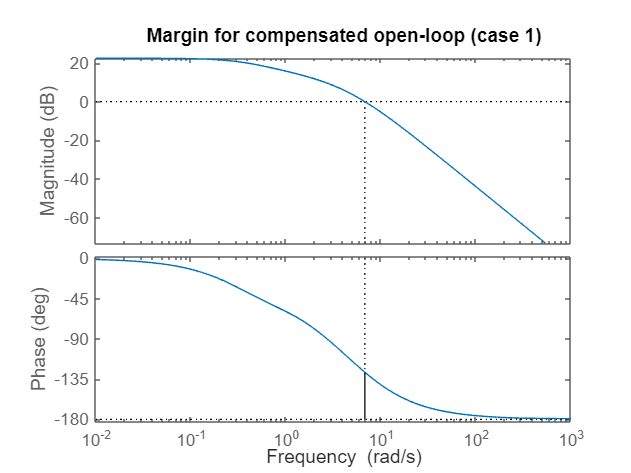

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G/(1+G), T); 
legend('Plant closed-loop','Compensated closed-loop');